# Assignment_01

## 1 Simple filters

### 1.1 Impulse responses, transfer functions

-  Find the poles and zeros of the filters with order 3 and 5 by calculating the roots of the corresponding polynomial with the `root` function

clear all; clc; 

% Declare transfer function variable z
z = tf('z');

% Transfer function of 3rd and 5th order running sum filters IR, H_RS3 and H_RS5
H_RS3 = (z^3+z^2+z^1+z^0)/(z^3);
H_RS5 = (z^5+z^4+z^3+z^2+z^1+z^0)/(z^5);

% Extract numerator and denominator polynomials from transfer functions
[num_RS3,den_RS3] = tfdata(H_RS3,'v');
[num_RS5,den_RS5] = tfdata(H_RS5,'v');

% Determine poles and zeros by taking the roots of both polynomials
poles_RS3 = roots(den_RS3);
zeros_RS3 = roots(num_RS3);
poles_RS5 = roots(den_RS5);
zeros_RS5 = roots(num_RS5);

- Plot the poles, the zeros and the frequency response of the filters using `zplane` and `freqz`

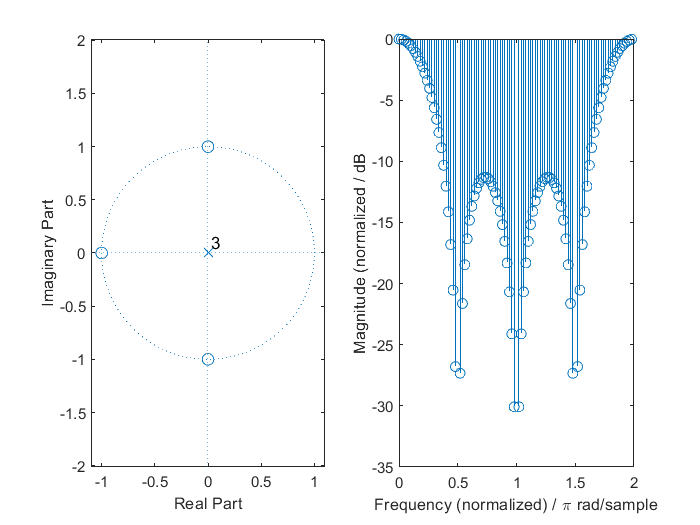

% Compute the frequency responses of both filter's IR
[h_RS3,w_RS3] = freqz(num_RS3,den_RS3,100,"whole"); 
[h_RS5,w_RS5] = freqz(num_RS5,den_RS5,100,"whole"); 

% Plot of 3rd order running sum filter IR's poles and zeros in z-plane and frequency response
figure("Name", "z-plane pole-zero and frequency response plot for 3rd order running sum filter IR");
subplot(1,2,1)
zplane(zeros_RS3,poles_RS3)
subplot(1,2,2)
stem(w_RS3/pi,mag2db(abs(h_RS3/max(h_RS3))))
ax = gca;
ax.XLim = [0 2]; 
xlabel('Frequency (normalized) / \pi rad/sample')
ylabel('Magnitude (normalized / dB')

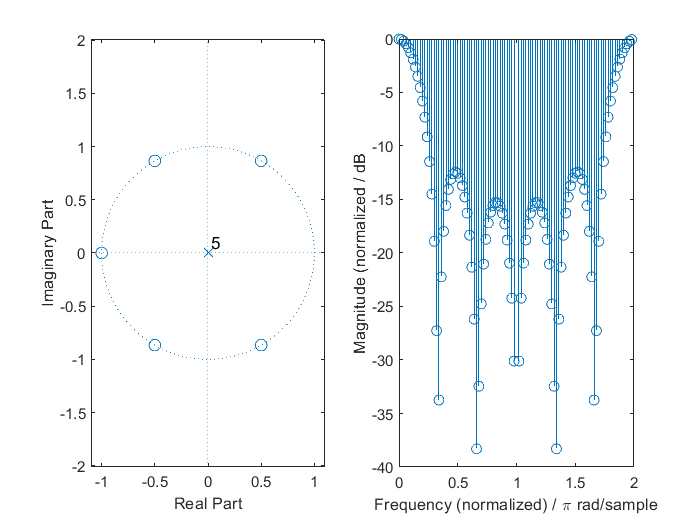

% Plot of 5th order running sum filter IR's poles and zeros in z-plane and frequency response
figure("Name", "z-plane pole-zero and frequency response plot for 5th order running sum filter IR");
subplot(1,2,1)
zplane(zeros_RS5,poles_RS5)
subplot(1,2,2)
stem(w_RS5/pi,mag2db(abs(h_RS5/max(h_RS5))))
ax = gca;
ax.XLim = [0 2]; 
xlabel('Frequency (normalized) / \pi rad/sample')
ylabel('Magnitude (normalized / dB')

- What happens to the frequency response when considering a moving average rather than a running sum? Recall, that the impulse response of the moving average $h_{\textrm{MA}} \left(n\right)$ is the impulse response of the running sum normalized by the length of the impulse response $N_0 =N+1$:


$$h_{\textrm{MA}} \left(n\right)=\frac{1}{N_0 }\cdot h_{\textrm{RS}}$$


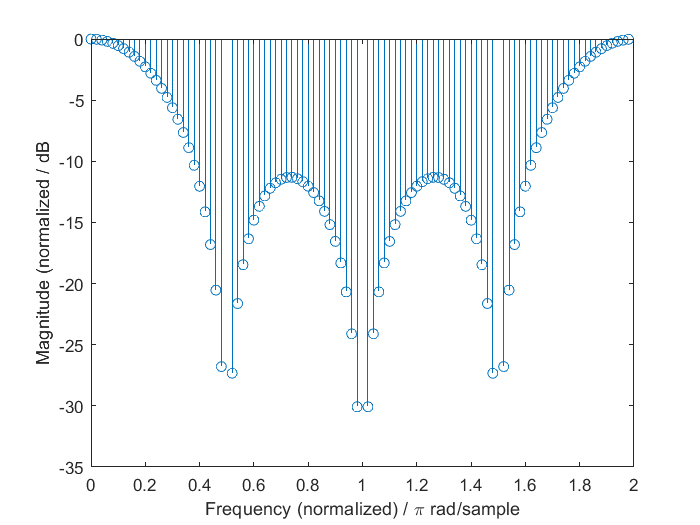

% Compute the moving average IR according to the formula above
h_MA3 = 1/4 * h_RS3;
h_MA5 = 1/6 * h_RS5; 

% Plot the frequency response of the 3rd and 5th order moving average
figure("Name","3rd order moving average frequency response")
stem(w_RS3/pi,mag2db(abs(h_MA3/max(h_MA3))))
xlabel('Frequency (normalized) / \pi rad/sample')
ylabel('Magnitude (normalized / dB')

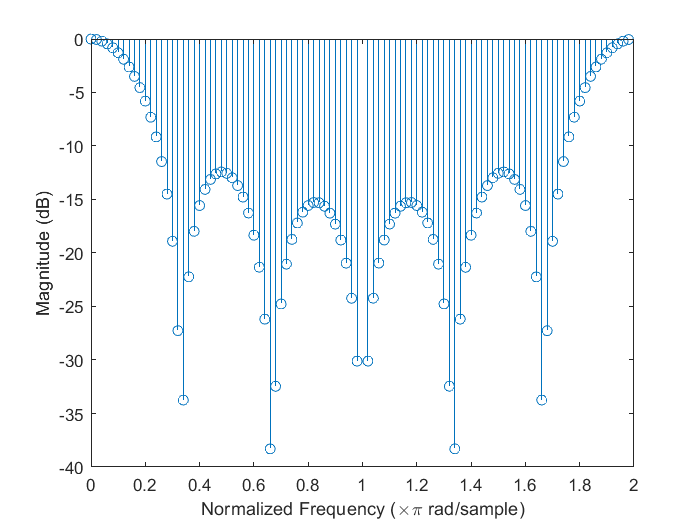

figure("Name","5th order moving average frequency response")
stem(w_RS5/pi,mag2db(abs(h_MA5/max(h_MA5))))
xlabel('Normalized Frequency (\times\pi rad/sample)')
ylabel('Magnitude (dB)')

- Some frequencies are heavily suppressed (attenuated) in these filters. Is there a simple way to enhance (that means to amplify) these frequencies rather than to attenuate them? 

Yes - place LHP poles at the wanted frequencies to amplify the signal. 

- Design a filter that blocks the normalized frequency of 0.1 by placing 4 zeros in the z-plane. Make sure the filter returns real-values outputs when fed with real-valued inputs by placing complex-conjugate pairs of poles and zeros.

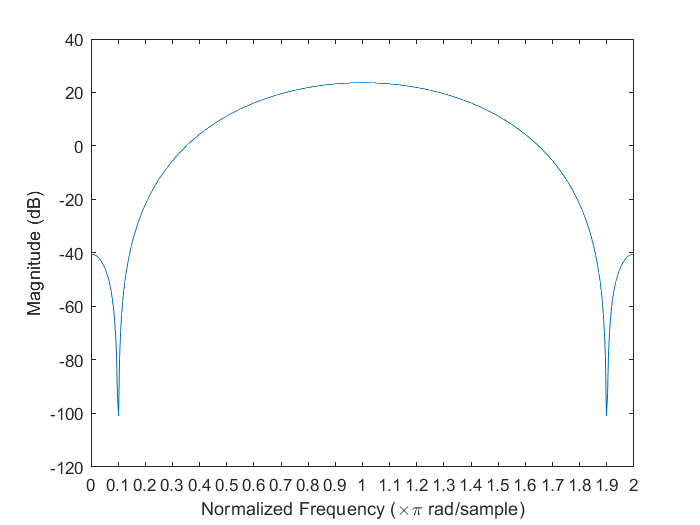

% Zeros of filter transfer function
Z = [exp(1i*0.1*pi) exp(-1i*0.1*pi) exp(1i*0.1*pi) exp(-1i*0.1*pi)];

% Choose gain K of transfer function
K = 1;

% Filter transfer function
H = zpk(Z,[],K);

% Plot frequency response
freq_resp_plot(H,"Frequency response of filter with 4 zeros")

- Add to the previous filter 4 poles lying on a circle with a radius $R<1$ (you chose $R$) at angles identical to the angles of the zeros. How does the frequency response change when you increase $R$ and when $R$ approaches 1? 

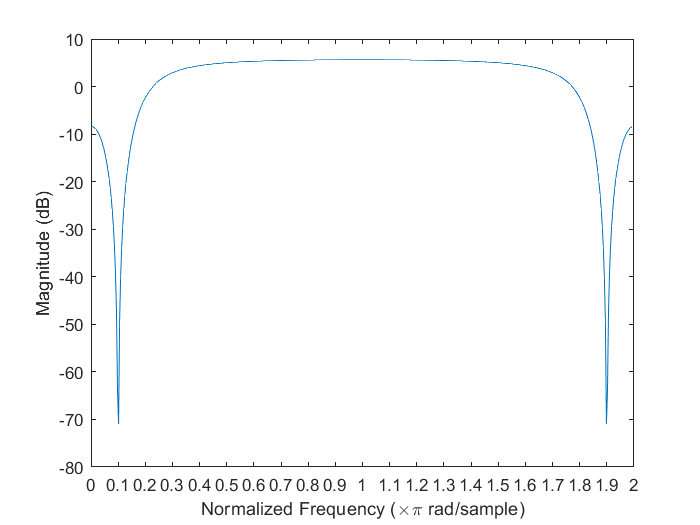

% Choose radius R
R =0.7;

% Poles of filter transfer function
P = [R*exp(1i*0.1*pi) R*exp(-1i*0.1*pi) R*exp(1i*0.1*pi) R*exp(-1i*0.1*pi)];

% Add denominator to filter transfer function
H = zpk(Z,P,K);

% Plot frequency response of new filter transfer function 
freq_resp_plot(H,"Frequency response of filter with 4 zeros and 4 poles")

### 1.2 The power of poles and zeros

Now that we have some routine with zeros and poles, let’s do something fun: 

- Place poles and zeros such that you generate a low-pass filter (i.e., passing the low frequencies)

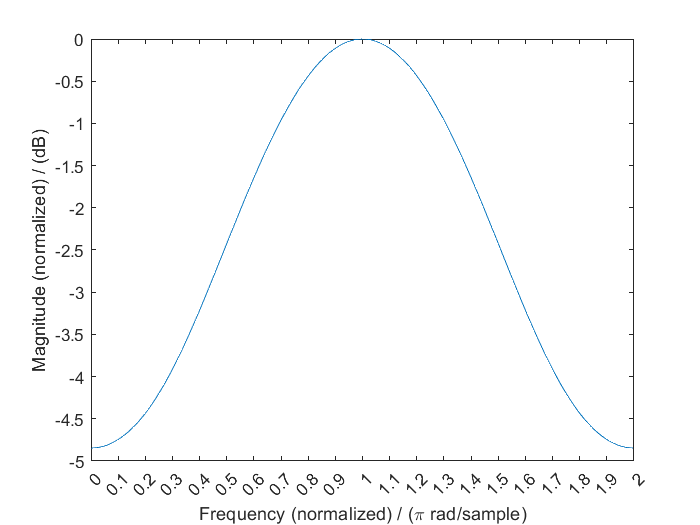

% Poles and zeros for lowpass filter 
P_LP = []; Z_LP = [0.2*exp(1i*pi/4) 0.2*exp(-1i*pi/4)];  
H_LP = zpk(Z_LP,P_LP,K); 
freq_resp_plot(H_LP, "Frequency response of 2nd order low-pass filter")

- Place poles and zeros such that you generate a high-pass filter (i.e., passing the high frequencies

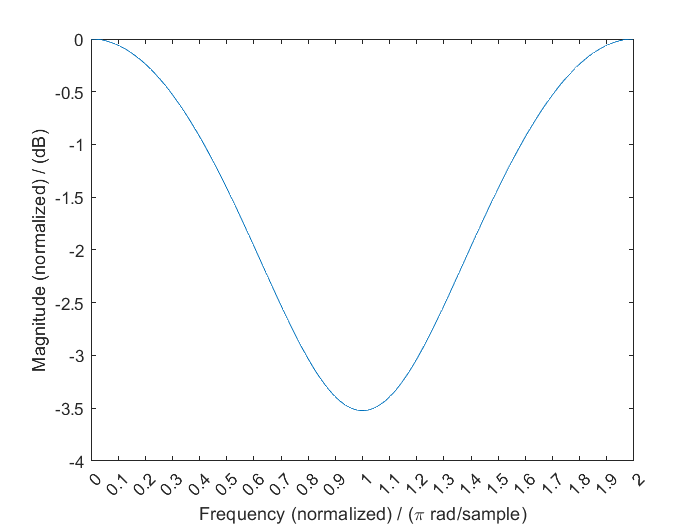

% Poles and zeros of highpass filter
P_HP = [0]; Z_HP = [-0.2]; 
H_HP = zpk(Z_HP,P_HP,K); 
freq_resp_plot(H_HP, "Frequency response of a 2nd order high-pass filter")

- Design a filter having five poles and zeros that passes all the frequencies (i.e., an all-pass filter)

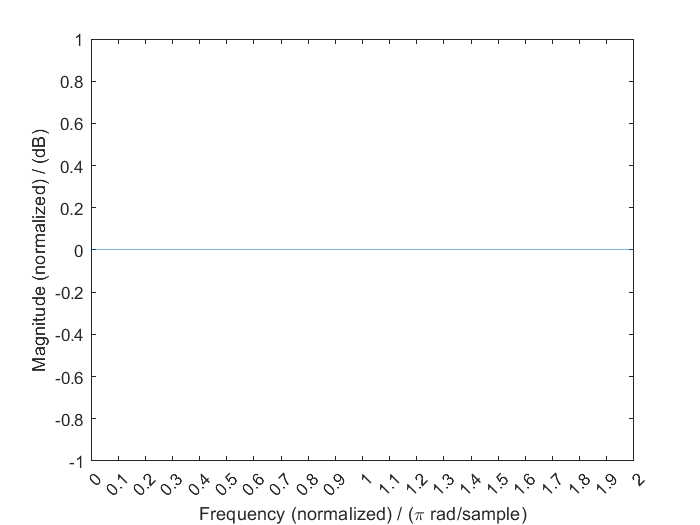

r = 0.5;
% Poles and zeros of all-pass filter 
P_AP = [r*(1) r*(exp(1i*pi/6)) r*(exp(-1i*pi/6)) r*(exp(1i*pi/3)) r*(exp(-1i*pi/3))]; 
Z_AP = [r*(1) r*(exp(1i*pi/6)) r*(exp(-1i*pi/6)) r*(exp(1i*pi/3)) r*(exp(-1i*pi/3))]; 
H_AP = zpk(Z_AP,P_AP,K);
freq_resp_plot(H_AP, "Frequency response of a 5th order all-pass filter")

- Generate a sinusoid at some sampling frequency and pass it through your filters. Plot the original signal and the resulting signal in the time domain. What can you observe?

% Generate 100 Hz sinusoid sampled at fs = 201 Hz
fs = 201;               % Sampling frequency (in Hz)
T0 = 1;                 % Duration (in sec)
t = 0:1/fs:T0-1/fs;     % Time vector
sin_100 = sin(100*t);   % Signal vector

% Transform the sinusoid into the z-domain
syms n
f = sin(n);
ztrans(f)

$$ans = \frac{z\,\sin\left(1\right)}{z^{2}-2\,\cos\left(1\right)\,z+1}$$

% Pass the sinusoid through low-pass, high-pass and all-pass filters

% Inverse transform the signals back into the time-domain

% Plot the original sinusoid alongside its filtered versions
figure("Name", "Time domain plot of filtered sinusoids")
title("Time domain plot of filtered sinusoids")
plot(t,sin_100)

- Pick some sound file of your choice, process it by the filter and listen to it using sound or soundsc (watch the volume!)

- How do the suppressed frequencies depend on the chosen sampling frequency of the input signal?

How does the processing of the sound change when you use more/less poles/zeros? Can you already estimate the transfer function by looking at the pole-zero plot? Can you say anything about the expected gain and phase shift of single responses?